# **Planar robot Arms**

## **prerequisites:**

- Installation of Robotics toolbox Version 10.4 by Peter Corke [https://petercorke.com/toolboxes/robotics-toolbox/](https://petercorke.com/toolboxes/robotics-toolbox/)

- Familiar with basics of kinematics and Matlab

- Reference reading: Chapter 2 of Robotics Modelling, Planning and Control  by Bruno Siciliano, Lorenzo Sciavicco, Luigi Villani, and Giuseppe Oriolo  

## Objectives:

- Formulate kinematics equations for different planar robots

- Simulate kinematics and inverse kinematics

clear;
clc;

$$E = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & a_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

# **Single-Link planar**

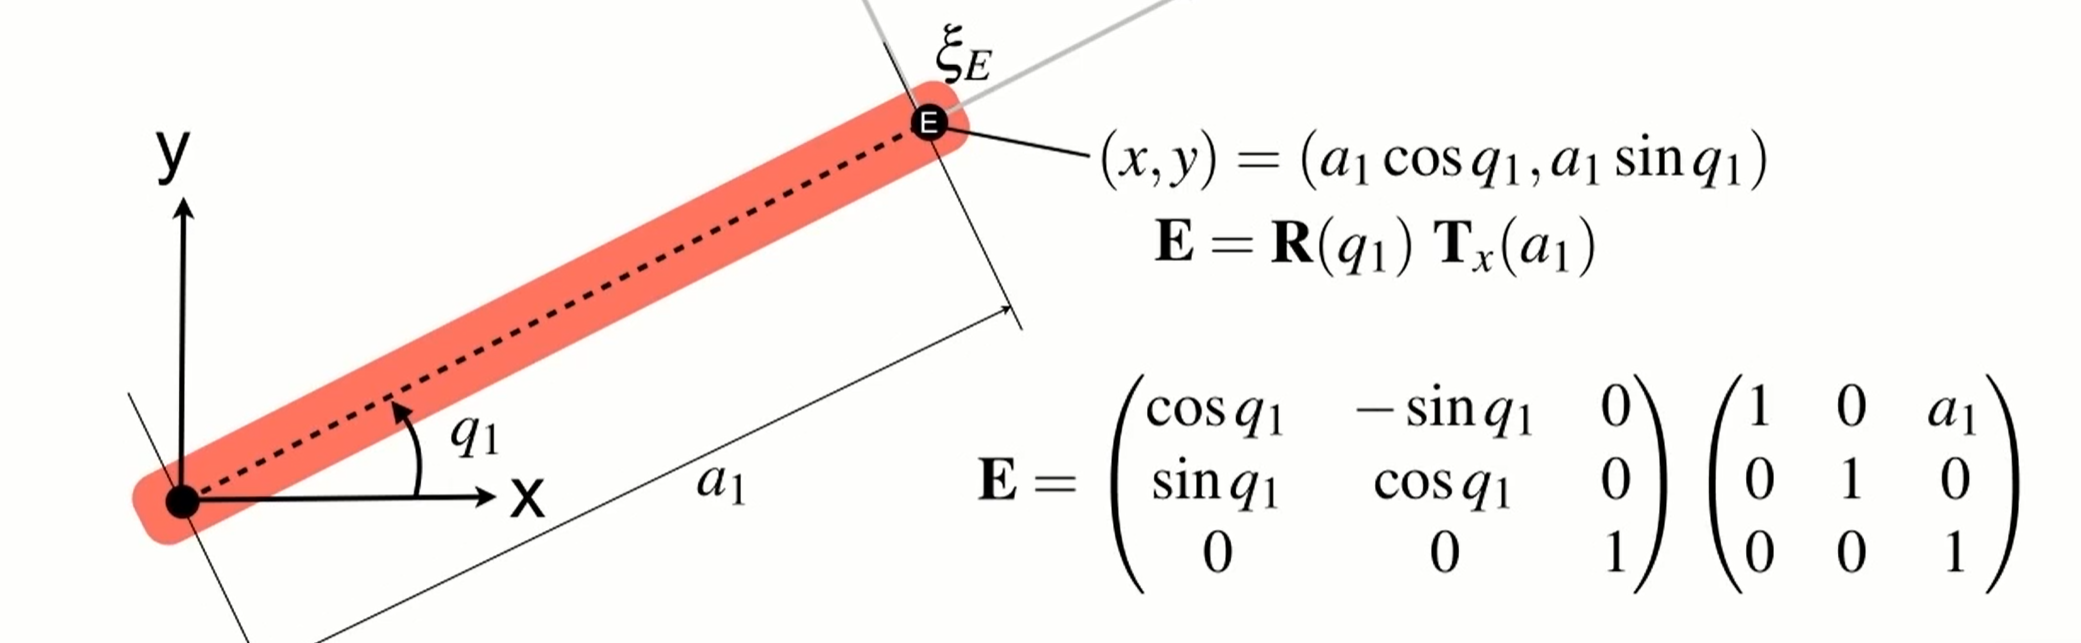

**Homogenous transform**

syms q1 a1

$$X = a_{1}\,\cos\left(q_{1}\right)$$

E = trchain2('R(q1) Tx(a1)',q1)

$$Y = a_{1}\,\sin\left(q_{1}\right)$$

X = E(1,3)
Y = E(2,3)

 
p1 = 
 
planar 1 link:: 1 axis, R, stdDH, slowRNE                        
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|          q|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


**Example**:

mdl_planar1
p1

 

ans = 
         0        -1         0         0
         1         0         0         1
         0         0         1         0
         0         0         0         1


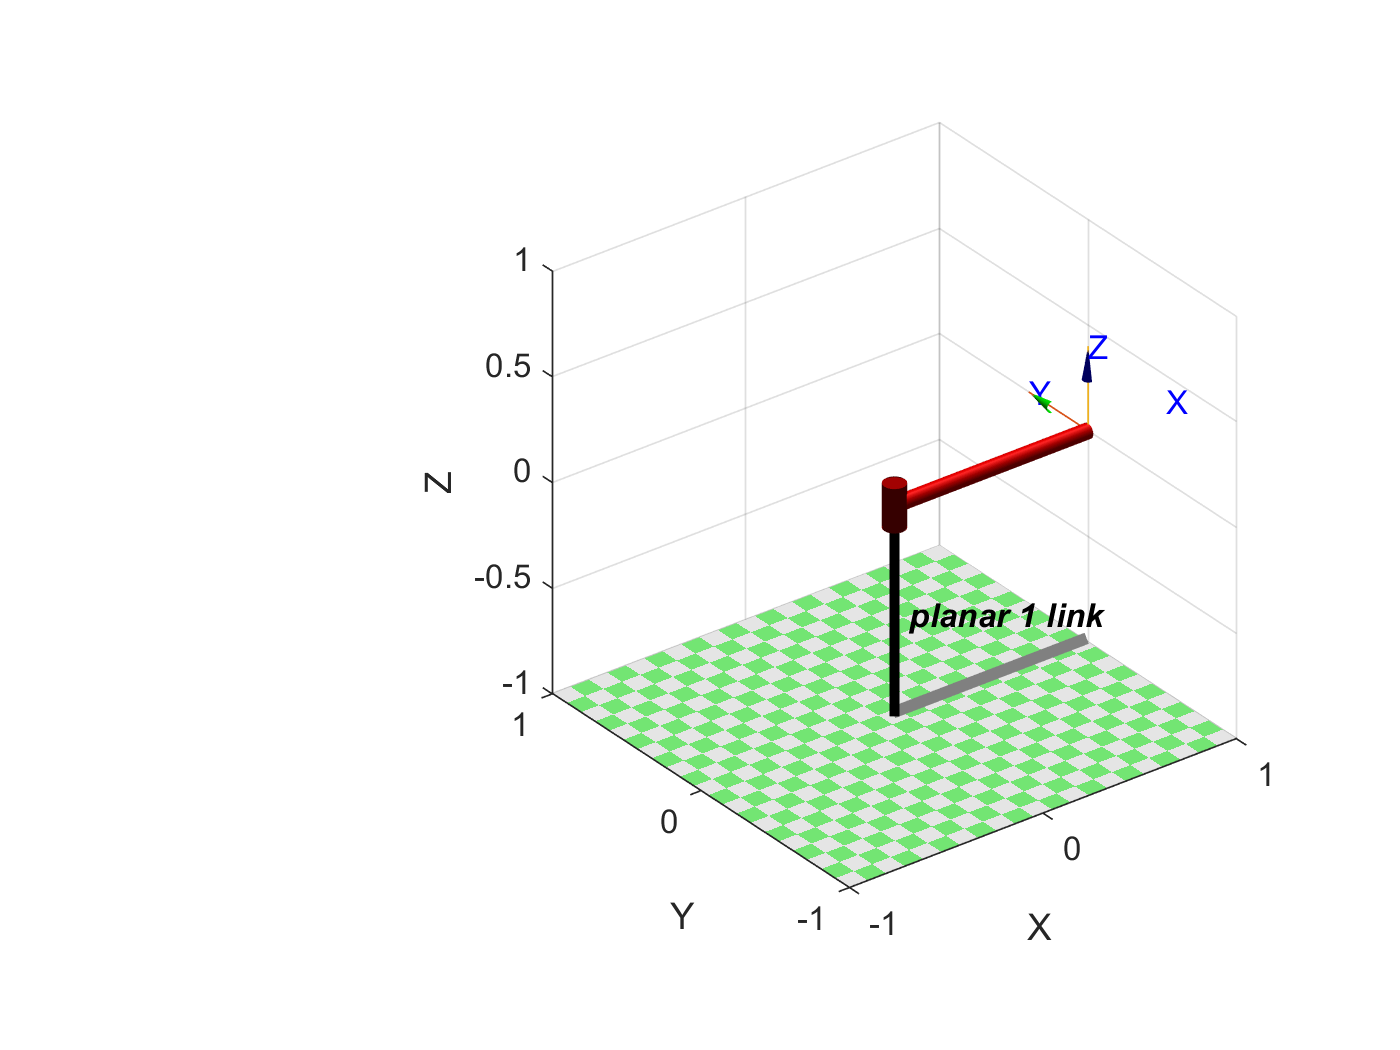

% forward kinematics specify joint angle
p1.fkine(pi/2)

Type* p1.teach* in the command window to show GUI 

%p1.teach

# **Two-Link planar**

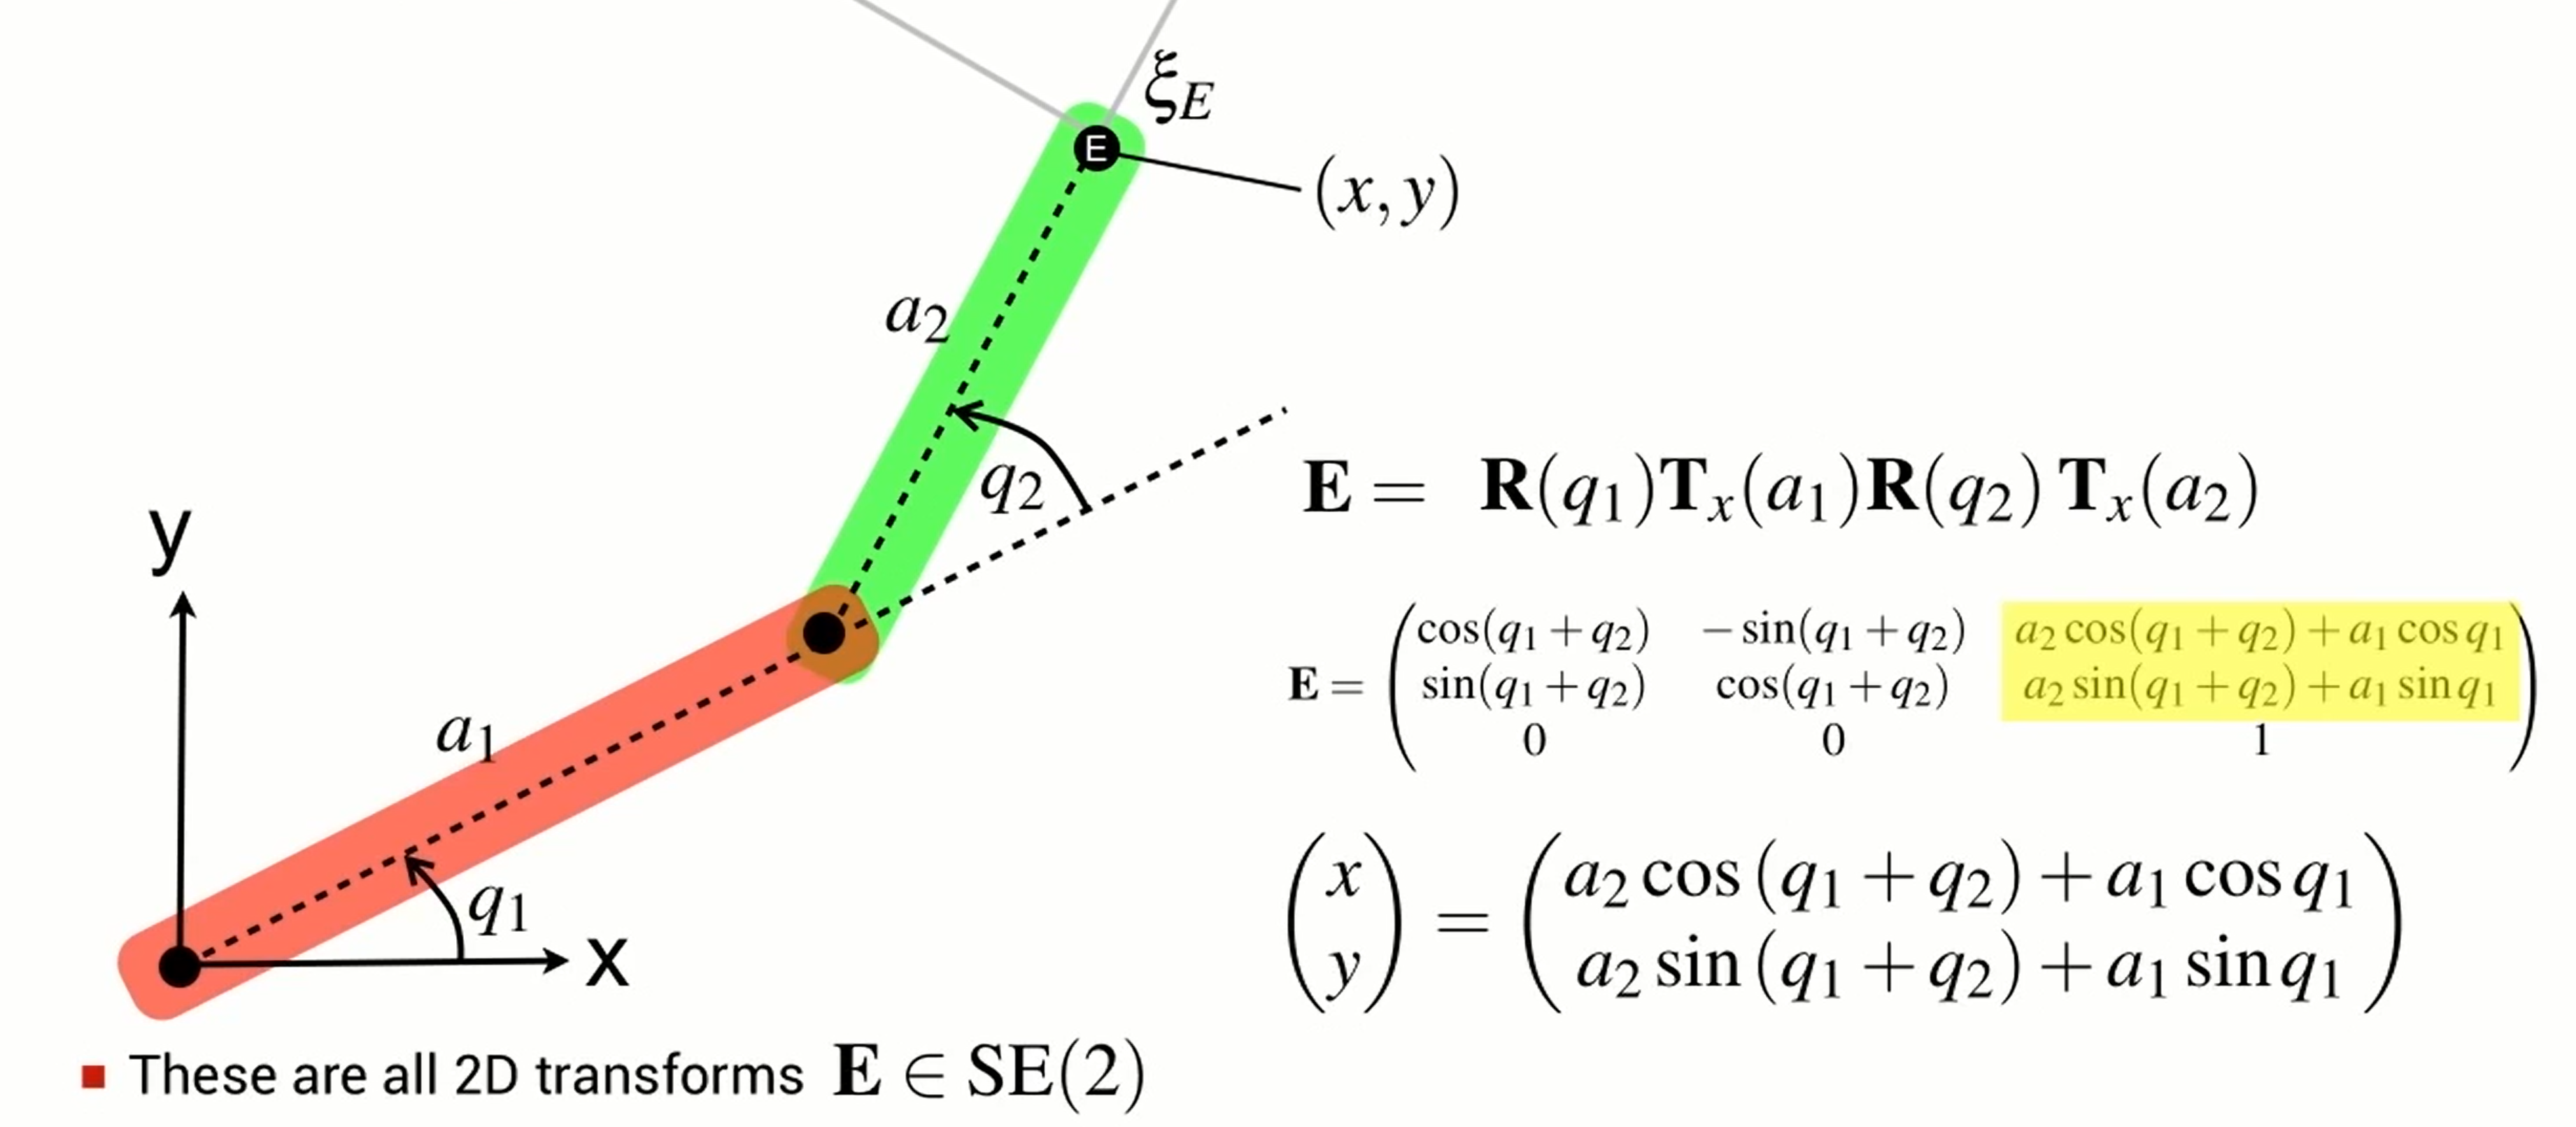

**Homogenous transform**

syms q1 q2 a1 a2
E = trchain2('R(q1) Tx(a1) R(q2) Tx(a2)',[q1,q2]);

$$E = \left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

E = simplify(E)

$$X = a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)$$

X = E(1,3)

$$Y = a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right)$$

Y = E(2,3)

**Example**:

mdl_planar2

 
p2 = 
 
planar 2 link:: 2 axis, RR, stdDH, slowRNE                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


p2

Type *p2.teach* in the command window to show GUI 

** Inverse Kinematics (Numerical)**

T = transl(1,1,0); % desired transform
initial_q = [0,0]; % initial guess of joint values

q =    -0.0000    1.5708


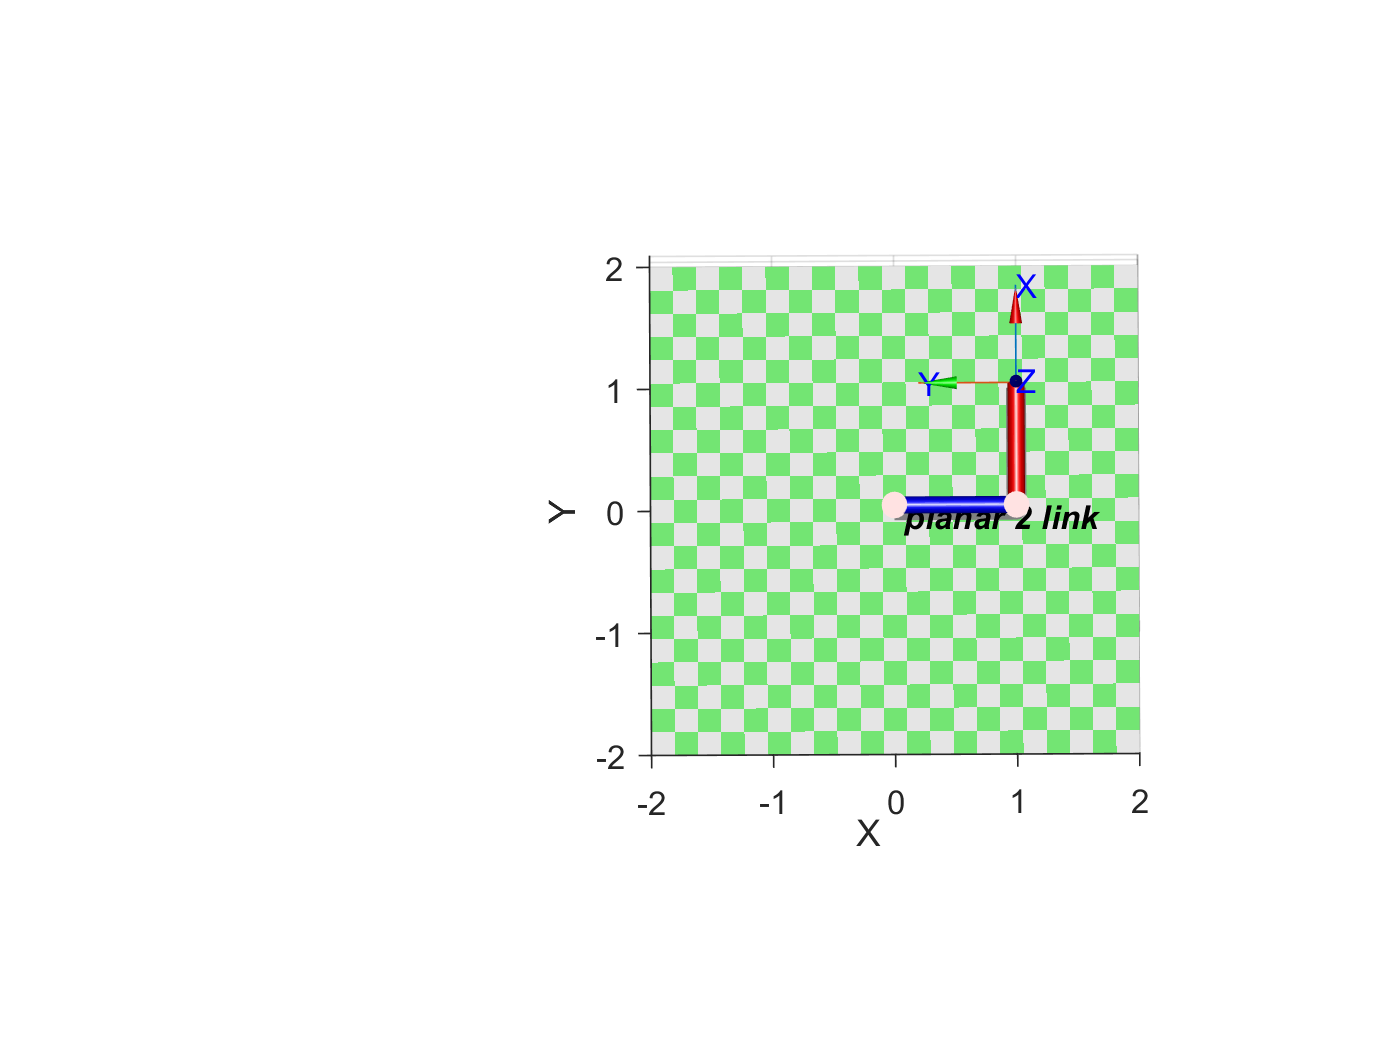

q = p2.ikine(T,initial_q,'mask',[1 1 0 0 0 0]) % [1 1 0 0 0 0 ] > only match x,y 

p2.plot(q);

# **Three-Link planar**

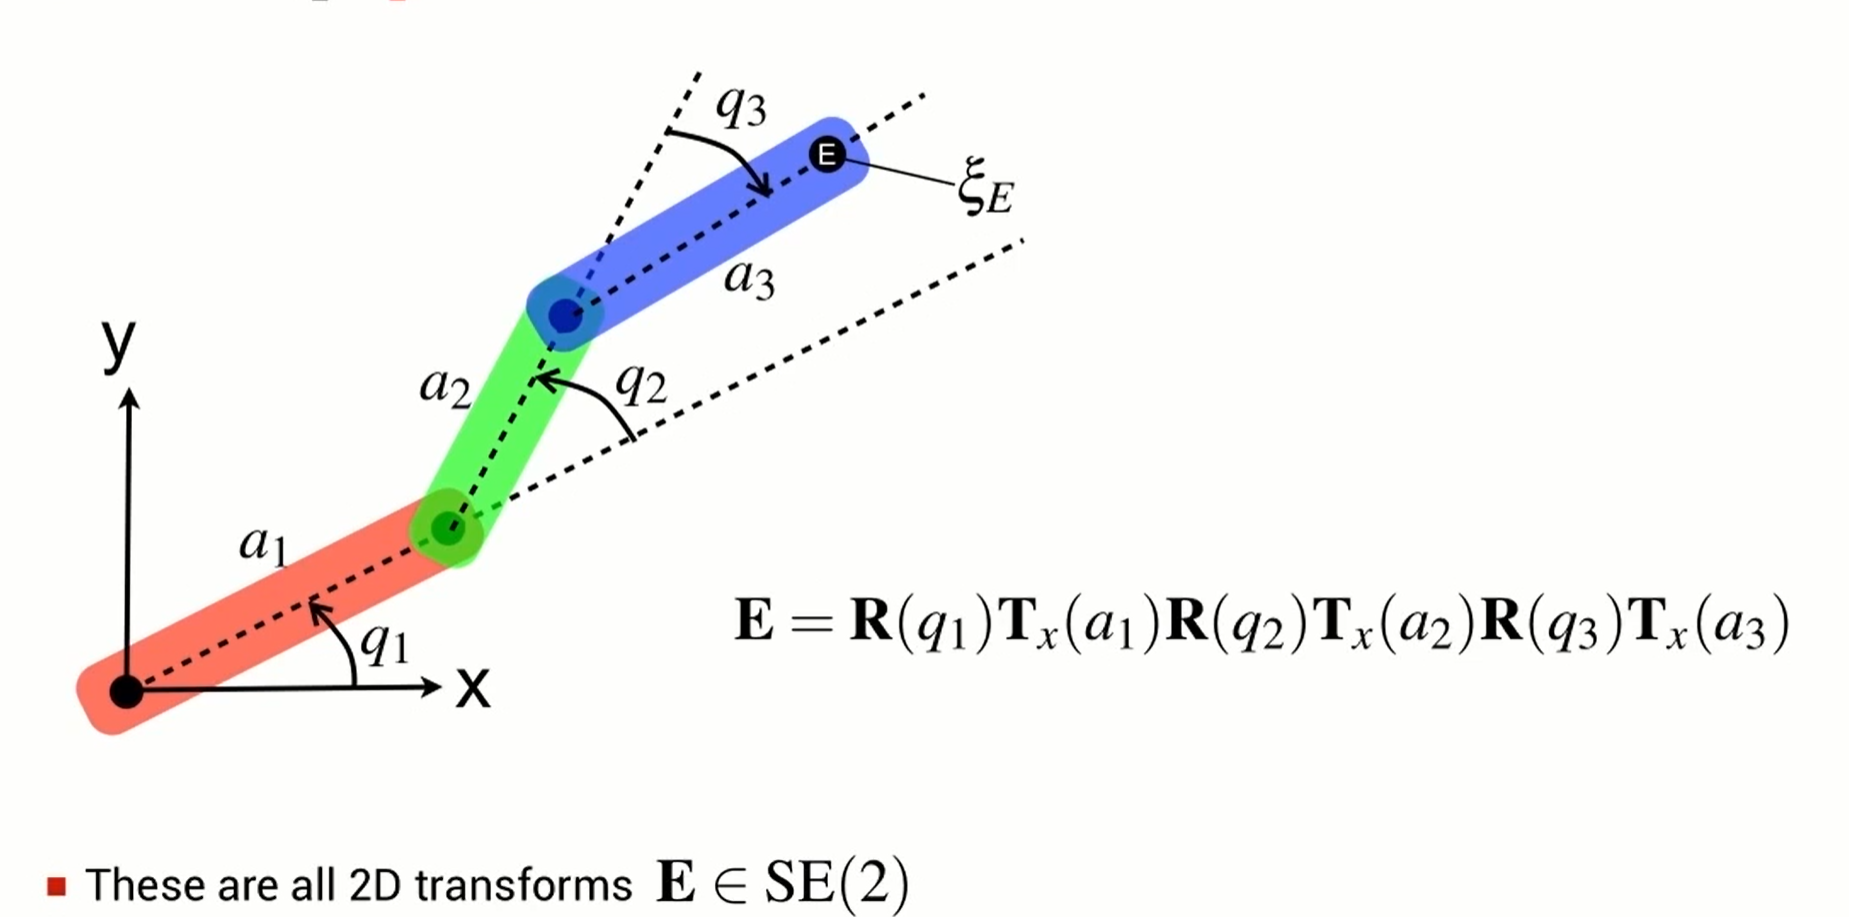

**Homogenous transform**

syms q1 q2 q3 a1 a2 a3
E = trchain2('R(q1) Tx(a1) R(q2) Tx(a2) R(q3) Tx(a3)',[q1,q2,q3]);
E = simplify(E)

$$E = \left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}+q_{3}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)+a_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right) & a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right)+a_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ 0 & 0 & 1 \end{array}\right)$$

X = E(1,3)

$$X = a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right)+a_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)$$

Y = E(2,3)

$$Y = a_{2}\,\sin\left(q_{1}+q_{2}\right)+a_{1}\,\sin\left(q_{1}\right)+a_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)$$

**Example**:

mdl_planar3
p3

 
p3 = 
 
planar 3 link:: 3 axis, RRR, stdDH, slowRNE                      
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
|  3|         q3|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


Type *p3.teach* in the command window to show GUI 

** Inverse Kinematics (Numerical)**

T = transl(1,0.5,pi/4)

T =     1.0000         0         0    1.0000
         0    1.0000         0    0.5000
         0         0    1.0000    0.7854
         0         0         0    1.0000


q = p3.ikine(T,[0.5,0.5,0],'mask',[1 1 0 0 0 0]) % [1 1 0 0 0 0 ] > only match x,y 

q =    -1.0806    1.5481    1.4753


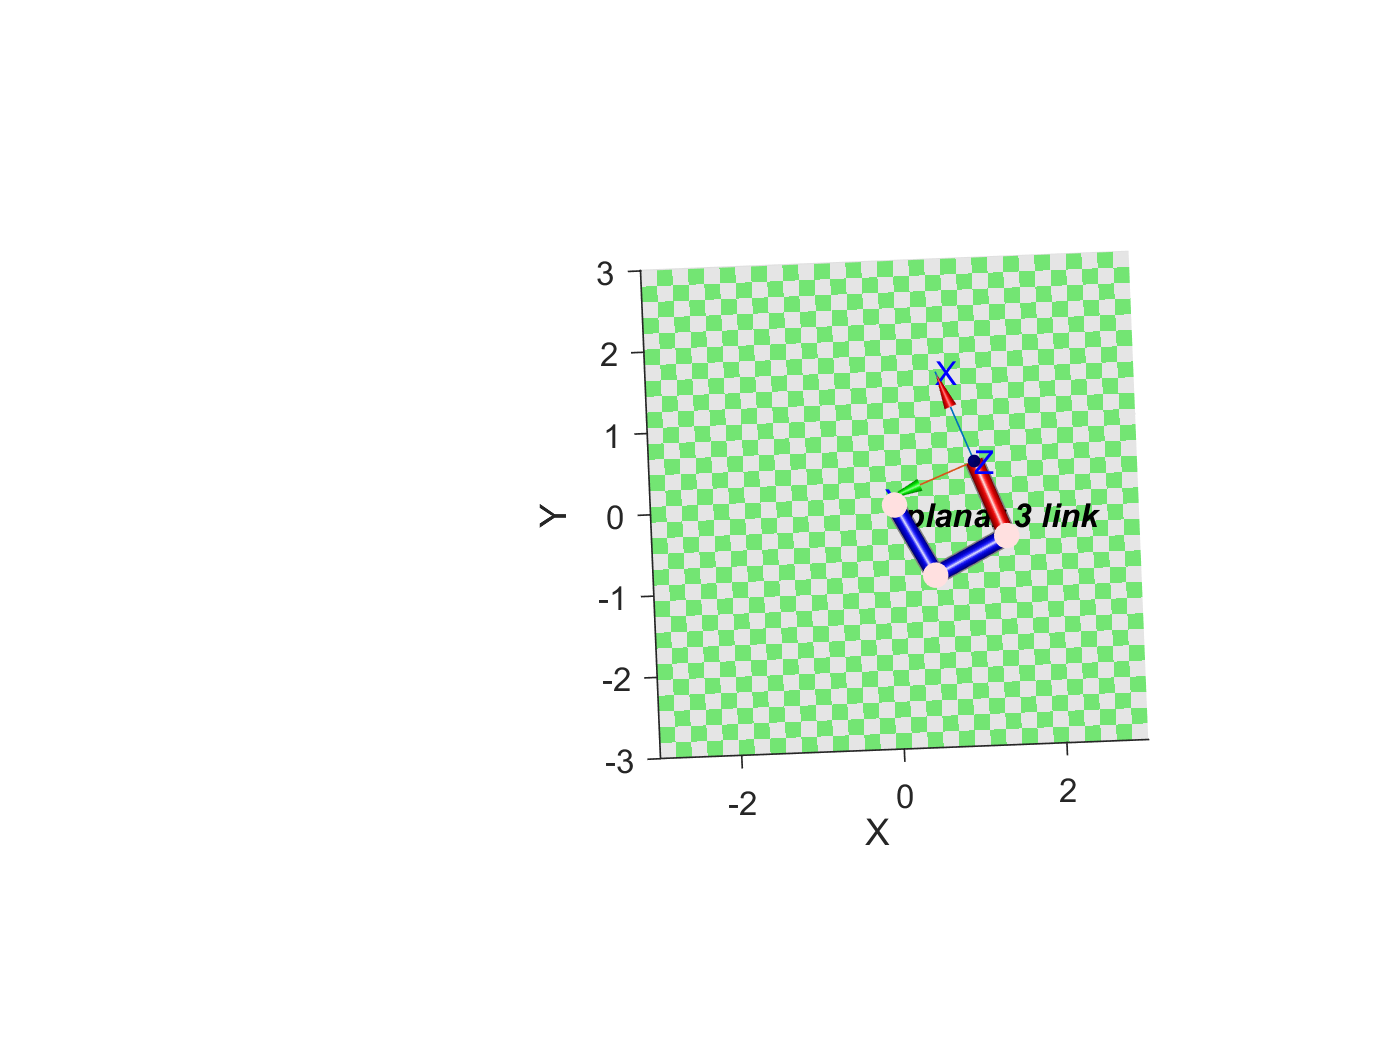

p3.plot(q);

# **References**

- Robotic arms and forward kinematics course from Robot Academy [https://robotacademy.net.au/masterclass/robotic-arms-and-forward-kinematics/](https://robotacademy.net.au/masterclass/robotic-arms-and-forward-kinematics/)